# 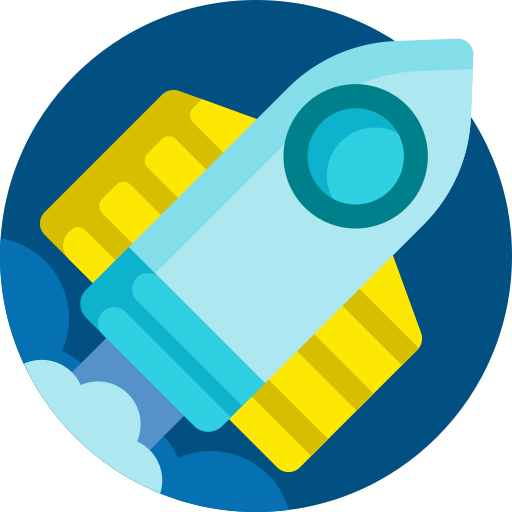 

# **MEC3079S: Control Systems**

# Chapter 10 — Steady-state error

## 10.1 Introduction

We previously introduced three performance metrics when analysing a control system, namely

- transient response,

- stability, and

- steady-state error.

We have now looked at both transient response for low-order systems and stability of systems in general, including quantifying the extent to which a system is stable. The final performance metric is the steady-state error response of a system.

Performance specifications of a closed-loop system will commonly specify the steady-state error requirement, which will indicate the type of signals that are expected be tracked, as well as how accurately the reference signal must be adhered to at steady-state.

### **10.1.1 Definition**

**Steady-state error** is the difference between the reference and output signal for a prescribed test input as $t\rightarrow\infty$, namely

$e(\infty)=\lim_{t\rightarrow\infty} \left( r(t)-y(t)\right) = r(\infty)-y(\infty)$.

If we have an equation for $E(s)=R(s)-Y(s)$, then we can determine $e(\infty)$ using final-value theorem:

$e(\infty)=\lim_{s\rightarrow 0}sE(s)$,

where $E(s)$ can be interpreted from the block diagram in Figure 10.1 as

$E(s)=\frac{1}{1+L(s)}R(s)$.

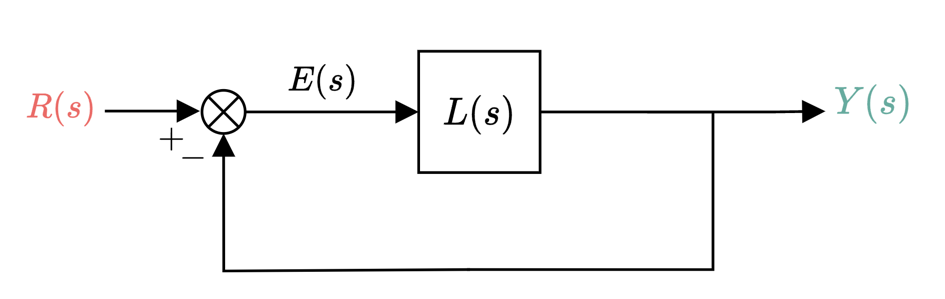

**Figure 10.1**: Block diagram of system in unity feedback.

Note that $L(s)=P(s)G(s)$ is made up of our plant, $P(s)$, which we cannot alter, and our feedback controller, $G(s)$, which we get to choose and will soon start to play around with.

The steady-state error analysis naturally requires that the system under consideration is stable. As such, the analysis tools that we will use are only applicable to BIBO stable systems. In practice, we should determine whether a system is closed-loop stable *before* assessing the steady-state error behaviour.

### 10.1.2 Evaluating steady-state error

Based on the definition of steady-state error, we can visualise this quantity by taking the difference between the time-domain reference and output signal as $t\rightarrow\infty$

$e(\infty)=\lim_{t\rightarrow\infty} \left( r(t)-y(t)\right) = r(\infty)-y(\infty)$.

This can be interpreted on a time-domain figure by considering the difference between the reference and output signals when the transient response has concluded. An example of this is shown in Figure 10.2 for a step-like reference signal.

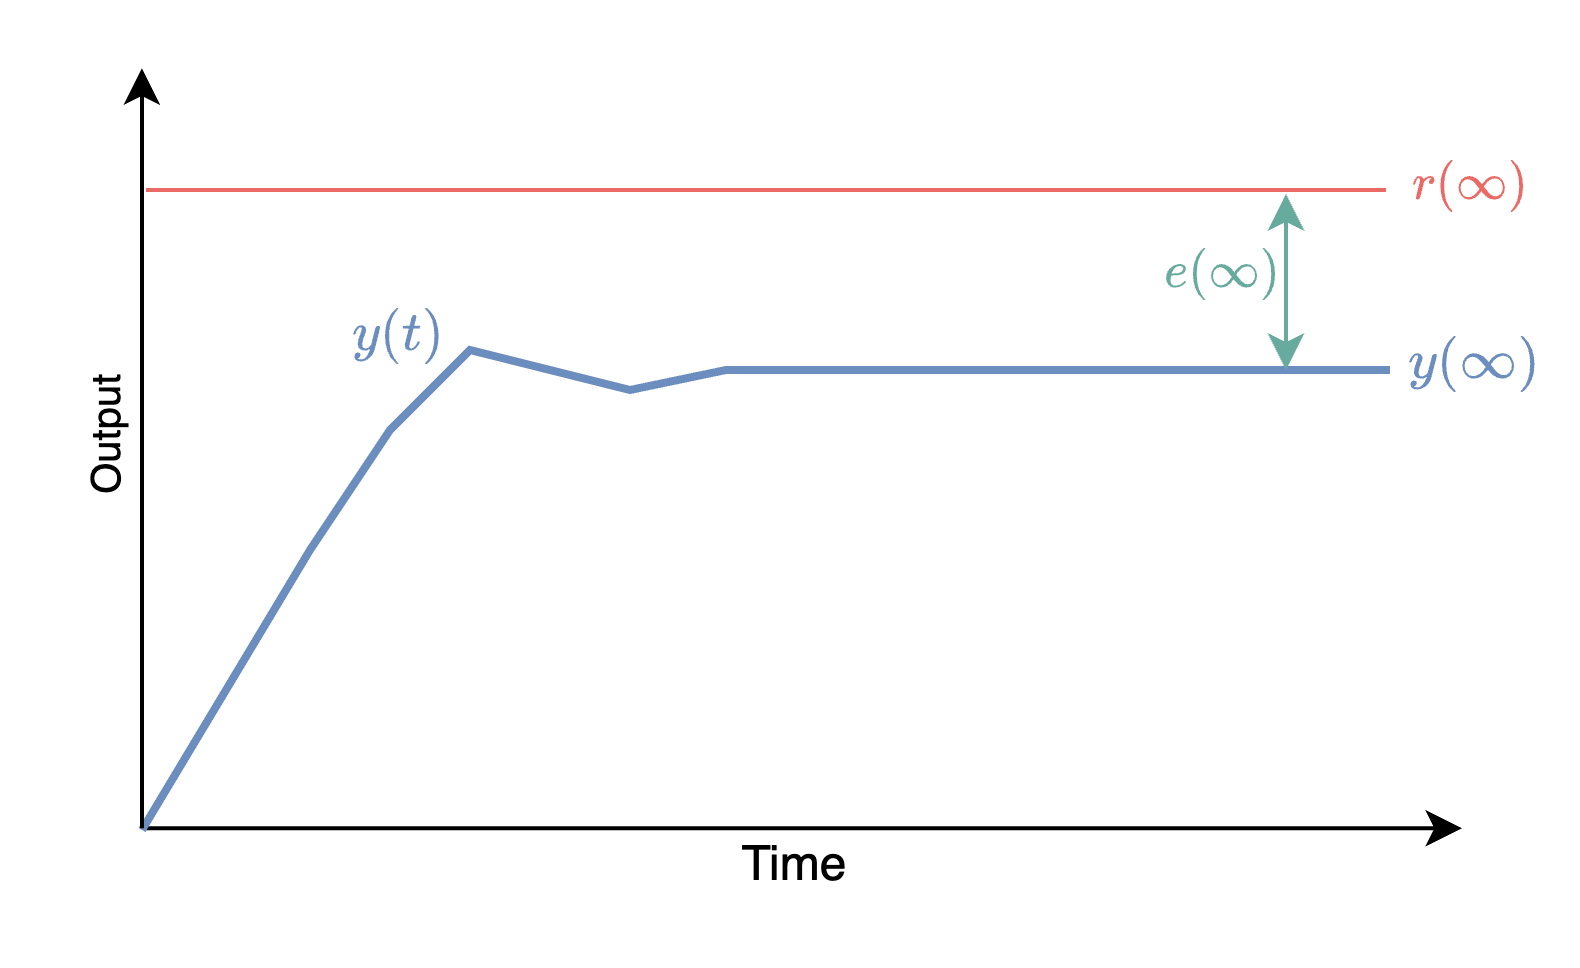

**Figure 10.2**: Finite steady-state error from step-like reference signal.

An example of the steady-state error for a ramp-like reference signal is shown in Figure 10.3.

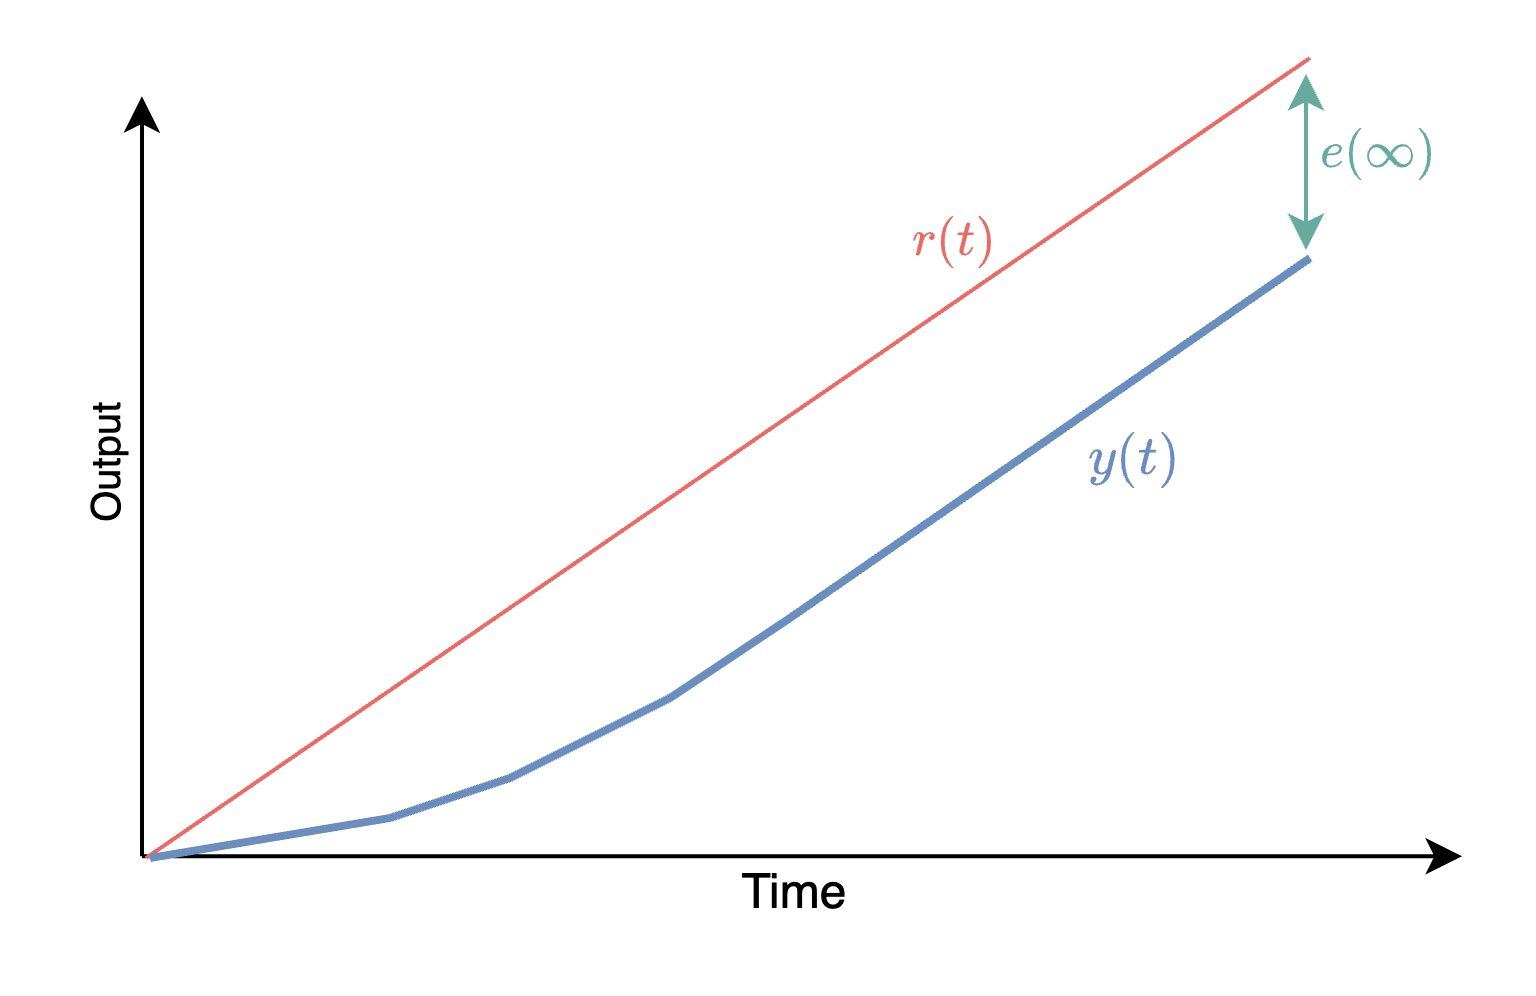

**Figure 10.3**: Finite steady-state error from ramp-like reference signal.

As we will see later, depending on the type of closed-loop system and reference input, the resulting steady-state error will either be 

- zero, 

- finite, or 

- infinitely large.

### 10.1.3 Sources of steady-state error

Steady-state error can result from a range of sources, with the main culprits listed below.

- Nonlinear effects

- Input disturbances

- System uncertainty

- System configuration

- Reference signal type

In any of the above cases, if we can model the closed-loop system sufficiently, then we will be able to quantify the expected steady-state error. We will also later consider steady-state error specifications and design for them.

## 10.2 Test inputs

We consider three main test inputs when assessing the steady-state error characteristics of position control systems. That is, we will consider reference signal, $r(t)$, as 

- a step input — corresponding to a constant position reference,

- a ramp input — corresponding to a constant velocity reference, and

- a parabolic input — corresponding to a constant acceleration reference signal.

**Figure 10.4**: System in unity feedback.

When applying these reference signals to the closed-loop system, we can imagine that, for example, our control system is a satellite dish, and we are trying to position it such that it tracks various objects. The step input can be likened to that of a test signal when tracking a satellite in geostationary orbit (stationary with respect to earth). The ramp input can be likened to that of a test signal when tracking a satellite moving at a constant velocity with respect to earth. Finally a parabolic input is useful when assessing the tracking capabilities when the reference signal has a constant acceleration, such as an accelerating missile. 

### 10.2.1 Step inputs

A *constant-position* reference signal is represented with a **step input**, where the step value, $a$, indicates the desired position value. Step inputs are useful in determining the ability of the control system to position itself with respect to a stationary target, such as a satellite in geostationary orbit. An antenna position control is an example of a system that can be tested for accuracy using step inputs.

Recall that the **step **function is defined in the time-domain as


$$r(t)=\left\{
        \begin{array}{ll}
           a, &  t \geq 0, \\
           0, & t < 0. \\
        \end{array}
    \right.$$


The corresponding representation in the Laplace domain is 


$$\begin{array}{ll}
R(s) =\frac{a}{s}.
\end{array}$$


%step input
syms a t real
syms s
r = piecewise(t>=0,a,t<0,0)

$$r = \left\{ \begin{array}{cl} a & \text{ if }0\leq t\\ 0 & \text{ if }t<0 \end{array}\right.$$

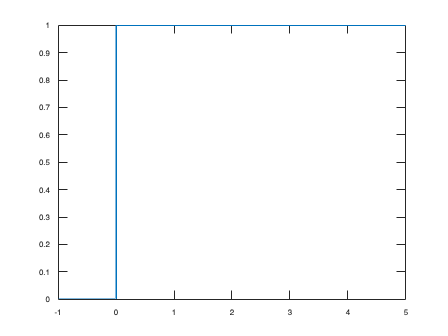


a = 1;
r = eval(r);

figure,clf
fplot(r,[-1 5],LineWidth=2)

### 10.2.2 Ramp inputs

**Ramp inputs** represent *constant-velocity* inputs to a position control system, based on their linearly increasing amplitude. These waveforms can be used to test a system's ability to follow a linearly increasing input or, equivalently, to track a target moving at a constant velocity. For example, a position control system tracking a satellite that moves across the sky at a constant angular velocity (relative to earth), as shown above, would be tested with a ramp input to evaluate the steady-state error between the satellite's angular position and that of the control system.

Recall that the **ramp **function, with slope $a$, is defined as


$$r(t)=\left\{
        \begin{array}{ll}
           at, &  t \geq 0, \\
           0, & t < 0. \\
        \end{array}
    \right.$$


The corresponding Laplace transform is 


$$\begin{array}{ll}
R(s) &=\frac{a}{s^2}.
\end{array}$$


%ramp input
syms a s t
r(t) = piecewise(t>=0,a*t,t<0,0)

$$r(t) = \left\{ \begin{array}{cl} a\,t & \text{ if }0\leq t\\ 0 & \text{ if }t<0 \end{array}\right.$$

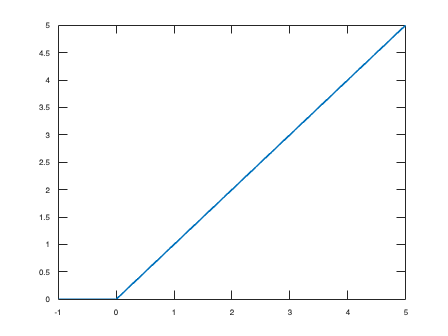


a = 1;
r(t) = eval(r(t));

figure,clf
fplot(r(t),[-1 5],LineWidth=2)

### 10.2.3 Parabolic inputs

**Parabolic inputs**, whose second derivatives are constant, represent *constant-acceleration* inputs to position control systems and can be used to represent accelerating reference targets, such as position system aiming towards an accelerating missile, to determine the steady-state error performance.

Recall that the **parabolic **function, with a constant acceleration of $a$, is defined as


$$r(t)=\left\{
        \begin{array}{ll}
           \frac{1}{2}at^2, &  t \geq 0, \\
           0, & t < 0. \\
        \end{array}
    \right.$$


The corresponding Laplace transform is 


$$\begin{array}{ll}
R(s) &=\frac{a}{s^3}.
\end{array}$$


%parabolic input
syms a s t
r(t) = piecewise(t>=0,a*t^2/2,t<0,0)

$$r(t) = \left\{ \begin{array}{cl} \frac{a\,t^{2}}{2} & \text{ if }0\leq t\\ 0 & \text{ if }t<0 \end{array}\right.$$

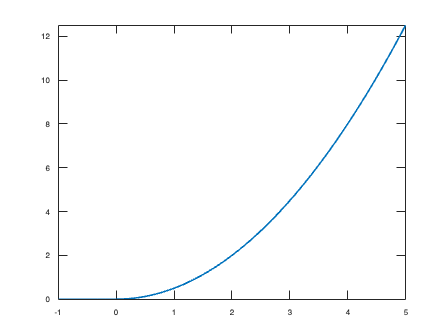


a = 1;
r(t) = eval(r(t));

figure,clf
fplot(r(t),[-1 5],LineWidth=2)

## 10.3 Final value theorem

Recall that final value theorem (FVT) determines the steady-state value of a signal, as the time parameter tends to infinity: $t\rightarrow\infty$. In the time domain, this can be represented as

$f(\infty)=\lim_{t\rightarrow\infty}f(t)$.

The corresponding final-value theorem application in the Laplace domain is given by

$f(\infty)=\lim_{s\rightarrow 0}sF(s)$.

Note that the above result is only valid for strictly stable system responses. We will make use of final-value theorem to calculate the steady-state error of classes of systems for our range of test inputs.

## 10.4 Determining steady-state error

### 10.4.1 Definition

Recall that we can describe $L(s)$ as


$$\begin{array}{ll}
L(s) &= A_L \frac{ (s-z_1)(s-z_2) \ldots (s-z_m) }{ (s-p_1)(s-p_2) \ldots (s-p_n)}, \\
&= A_L\frac{\prod_{i=1}^m (s-z_i)}{\prod_{i=1}^n (s-p_i)},
\end{array}$$


where $p_i$ and $z_i$ are the poles and zeros of $L(s)$, respectively. If $k\in\mathbb{N}_+$ represents the number of poles at the origin, then we can represent $L(s)$ as


$$\begin{array}{ll}
L(s) &= A_L \frac{ (s-z_1)(s-z_2) \ldots (s-z_m) }{ s^k(s-p_1)(s-p_2) \ldots (s-p_{n-k})}, \\
&= A_L\frac{\prod_{i=1}^m (s-z_i)}{s^k\prod_{i=1}^{n-k} (s-p_i)}.
\end{array}$$


We shall show shortly that the number of integrators in $L(s)$ is key in determining the steady-state error behaviour. 

**Figure 10.5**: System in unity feedback.

Considering the block diagram in Figure 10.5 of a unity-feedback control system, the reference tracking error is given by

$E(s)=R(s)-Y(s)$.

Using block diagram algebra, or first principles, we can then show that the reference signal is related to the tracking error by

$E(s)=\frac{1}{1+L(s)}R(s)$,

where $S(s)=\frac{1}{1+L(s)$ is the sensitivity function, as defined in **Chapter 8**. As we are interested in the steady-state error of $e(t)$, we apply final value theorem to $E(s)$, with the condition that the closed-loop system is stable, which gives us

$e(\infty)=\lim_{s\rightarrow 0}sE(s)=\lim_{s\rightarrow 0}\frac{s}{1+L(s)}R(s)$.

The resulting generalised $e(\infty)$ defined above will end up depending on the structure of $L(s)$ and $R(s)$, as will be shown in the following sections.

### 10.4.2 Step inputs

Given a unit step reference signal of $R(s)=1/s$, and using the formula above, the corresponding steady-error becomes

$e(\infty)=\lim_{s\rightarrow 0}\frac{s}{1+L(s)}R(s)=\lim_{s\rightarrow 0}\frac{s}{1+L(s)}\frac{1}{s}=\frac{1}{1+\lim_{s\rightarrow 0} L(s)}=\frac{1}{1+G_{dc}}$,

where $G_{dc}=\lim_{s\rightarrow 0}L(s)$ is the DC gain of the loop transfer function $L(s)$, as defined in **Chapter 7**. A time-domain visualisation is shown in Figure 10.6.

**Figure 10.6**: Finite steady-state error, $e(\infty)$, from step-like reference signal.

Formally

$G_{dc}=\lim_{s\rightarrow 0} L(s)=\lim_{s\rightarrow 0}A_L\frac{(s-z_1)(s-z_2)...(s-z_m)}{s^k(s-p_1)(s-p_2)...(s-p_{n-k})}$,

where


$$G_{dc}=\left\{
        \begin{array}{ll}
           A_L(-1)^{m+n}\frac{\prod_{i=1}^{m} z_i}{\prod_{i=1}^{n-k} p_i}, &  k=0, \\
           \infty, & k>0. \\
        \end{array}
    \right.$$


In other words, given that $n\geq m$, $L(s)$ will have a finite DC gain of $G_{dc}=A_L(-1)^{m+n}\frac{\prod_{i=1}^{m} z_i}{\prod_{i=1}^{n-k} p_i}$ if there are no integrators in the forward transfer function ($k=0$), and infinite gain if at least one integrator is present ($k>0$). Considering our steady-state error result for unit step inputs of

$e(\infty)=\frac{1}{1+G_{dc}}$,

we conclude that in order to achieve *zero steady-state error* for a step signal, we require an infinitely large DC gain, namely 

$G_{dc}=\lim_{s\rightarrow 0}L(s)=\infty$,

as this results in

$e(\infty)=\frac{1}{1+\infty}=0$.

However, if $G_{dc}$ is finite, then $e(\infty)$ will also be finite based on

$e(\infty)=\frac{1}{1+G_{dc}}$.

 In summary, for step reference signals and $k$ integrators in the forward transfer function

- if $k=0$: $0<|e(\infty)|<\infty$,

- if $k>0$: $|e(\infty)|=0$.

That is, for a step input to a unity-feedback system, the steady-state error will be zero if there is *at least* one pure integration in the forward path. If there are no integrators, then there will be a nonzero finite error.

#### Example 1

*Determine the steady-state error of *$L(s)=\frac{10}{1+s/10}$* when placed in unity-feedback and perturbed by a unit step reference signal.*

We must first determine whether the closed-loop system is stable. This is done by finding the roots of $1+L(s)$, which yields a single closed-loop pole at $p=-110$. The closed-loop pole is in the OLHP so the closed-loop system is indeed stable.

The DC gain of $L(s)$ is calculated as $G_{dc}=\lim_{s\rightarrow 0}L(s)=10$. We can then determine the steady-state error as

$e(\infty)=\frac{1}{1+G_{dc}}=\frac{1}{1+10}=0.091$.

The code below shows the graphical result, which matches our prediction using final-value theorem.

%Example
clear
s = tf('s')


s =
 
  s
 
Continuous-time transfer function.
Model Properties


L = 10/(1+s/10);
T = feedback(L,1);

poleT = pole(T)

poleT = -110


g_dc = dcgain(L)

g_dc = 10

e_inf = 1/(1+g_dc)

e_inf = 0.0909

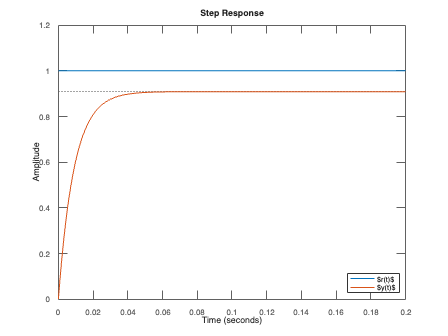


R = 1/s;

figure,hold on
step(R*s)
step(T)

legend('$r(t)$','$y(t)$','Interpreter','latex',location='southeast')

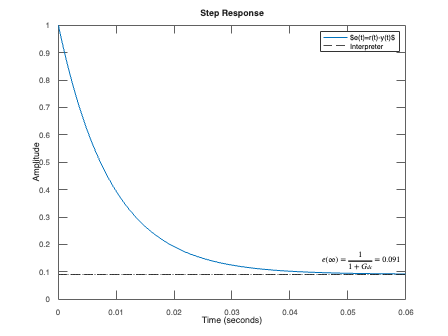


figure,hold on
step(1/(1+L))
yline(1/(1+g_dc),'--k',['$e(\infty)=\frac{1}{1+G_{dc}}=$',num2str(1/(1+g_dc),2)],Interpreter='latex')
legend('$e(t)=r(t)-y(t)$','Interpreter','latex')

#### Example 2

*Determine the steady-state error of *$L(s)=\frac{10}{s(1+s/10)}$* when placed in unity-feedback and perturbed by a unit step reference signal.*

We must first determine whether the closed-loop system is stable. This is done by finding the roots of $1+L(s)$, which yields two closed-loop poles at $p_{1,2}=-5\pm j8.66$. The closed-loop poles are in the OLHP so the closed-loop system is therefore stable.

The DC gain of $L(s)$ is calculated as $G_{dc}=\lim_{s\rightarrow 0}L(s)=\infty$, as a result of having an integrator in $L(s)$. We can then determine the steady-state error as

$e(\infty)=\frac{1}{1+G_{dc}}=\frac{1}{1+\infty}=0$.

The code below shows the graphical result, which matches our prediction using final-value theorem.

%Example
s = tf('s');

L = 10/s/(1+s/10);
T = feedback(L,1);

polesT = pole(T)

polesT =   -5.0000 + 8.6603i
  -5.0000 - 8.6603i



g_dc = dcgain(L)

g_dc = Inf

e_inf = 1/(1+g_dc)

e_inf = 0

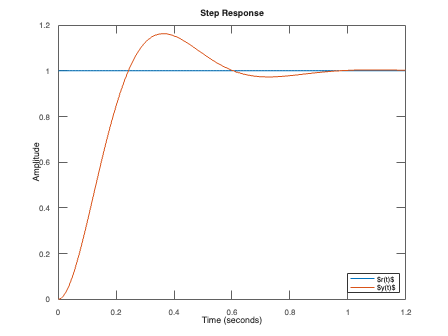


R = 1/s;

figure,hold on
step(R*s)
step(T)

legend('$r(t)$','$y(t)$',Interpreter = 'latex',location='southeast')

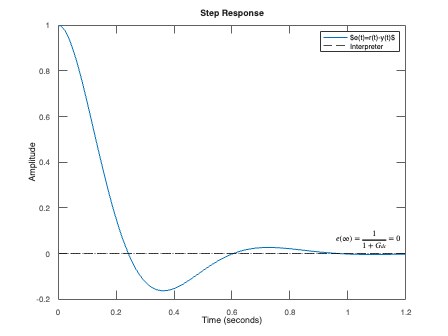


figure,hold on
step(1/(1+L))
yline(1/(1+g_dc),'--k',['$e(\infty)=\frac{1}{1+G_{dc}}=$',num2str(1/(1+g_dc),2)],Interpreter='latex')
legend('$e(t)=r(t)-y(t)$',Interpreter = 'latex')

### 10.4.3 Ramp inputs

Given a unit ramp input of $R(s)=1/s^2$, the corresponding steady-error is

$e(\infty)=\lim_{s\rightarrow 0}\frac{s}{1+L(s)}R(s)=\lim_{s\rightarrow 0}\frac{s}{1+L(s)}\frac{1}{s^2}=\lim_{s\rightarrow 0}\frac{1}{s+ sL(s)}=\frac{1}{\lim_{s\rightarrow 0}sL(s)}$.

Therefore, in order to have zero steady-state error tracking for a ramp input, we required $\lim_{s\rightarrow 0}sL(s)=\infty$. Reflecting on the forward transfer function of


$$\begin{array}{ll}
L(s) &= A_L \frac{ (s-z_1)(s-z_2) \ldots (s-z_m) }{ s^k(s-p_1)(s-p_2) \ldots (s-p_{n-k})}, \\
&= A_L\frac{\prod_{i=1}^m (s-z_i)}{s^k\prod_{i=1}^{n-k} (s-p_i)},
\end{array}$$


we require $k\geq 2$ in order to satisfy $\lim_{s\rightarrow 0}sL(s)=\infty$, which results in $e(\infty)=0$. 

If $k=1$, then 

$\lim_{s\rightarrow 0}sL(s)=A_L(-1)^{m+n-1}\frac{z_1z_2...z_m}{p_1p_2...p_{n-1}}$,

and $e(\infty)$ will be finite. This leads to a constant error, which can be thought of as a ramping output response with the same gradient as the reference signal, but with a constant offset, as shown in Figure 10.7.

**Figure 10.7**: Finite steady-state error, $e(\infty)$, from step-like reference signal.

If $k=0$, then 

$\lim_{s\rightarrow 0}sL(s)=A_L(-1)^{m+n}\frac{z_1z_2...z_m}{p_1p_2...p_n}s=0$,

and the corresponding $e(\infty)=\infty$. This results in a diverging ramp, where the output has a smaller gradient than that of the reference. In summary, for unit ramp reference signals, the steady-state error will be 


$$e({\infty})=\left\{
        \begin{array}{ll}
           \infty, &  k=0, \\
           A_L(-1)^{m+n-1}\frac{z_1z_2...z_m}{p_1p_2...p_{n-1}}, &  k=1, \\
           0, & k>1. \\
        \end{array}
    \right.$$


#### Example 1

*Determine the steady-state error of *$L(s)=\frac{10}{1+s/10}$* when placed in unity-feedback and perturbed by a unit ramp reference signal.*

We must first determine whether the closed-loop system is stable. This is done by finding the roots of $1+L(s)$, which yields a single closed-loop pole at $p=-110$. The closed-loop pole is in the OLHP so the closed-loop system is indeed stable.

We then determine $\lim_{s\rightarrow 0}sL(s)=0$, which we use to determine the steady-state error as

$e(\infty)=\frac{1}{\lim_{s\rightarrow 0}sL(s)}=\infty$.

The code below shows the graphical result, which matches our prediction using final-value theorem.

%Example
clear
s = tf('s')


s =
 
  s
 
Continuous-time transfer function.
Model Properties


L = 10/(1+s/10);
T = feedback(L,1);

poleT = pole(T)

poleT = -110

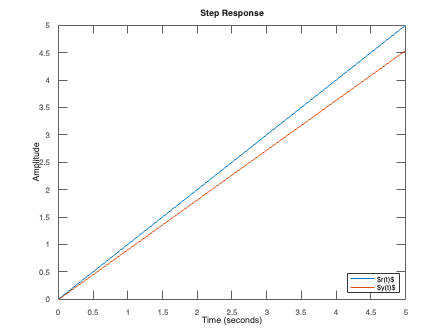



R = 1/s^2;

figure,hold on
step(R*s,5)
step(T/s,5)

legend('$r(t)$','$y(t)$',Interpreter = 'latex',location='southeast')

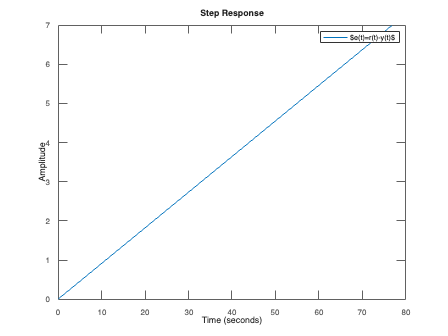


figure,hold on
step(1/(1+L)/s)
legend('$e(t)=r(t)-y(t)$',Interpreter = 'latex')

#### Example 2

*Determine the steady-state error of *$L(s)=\frac{10}{s(1+s/10)}$* when placed in unity-feedback and perturbed by a unit ramp reference signal.*

We must first determine whether the closed-loop system is stable. This is done by finding the roots of $1+L(s)$, which yields two closed-loop poles at $p_{1,2}=-5\pm j8.66$. The closed-loop poles are in the OLHP so the closed-loop system is therefore stable.

We then determine $\lim_{s\rightarrow 0}sL(s)=10$, which we used to determine the steady-state error as

$e(\infty)=\frac{1}{\lim_{s\rightarrow 0}sL(s)}=0.1$.

The code below shows the graphical result, which matches our prediction using final-value theorem.

%Example
s = tf('s');

L = 10/s/(1+s/10);
T = feedback(L,1);

polesT = pole(T)

polesT =   -5.0000 + 8.6603i
  -5.0000 - 8.6603i


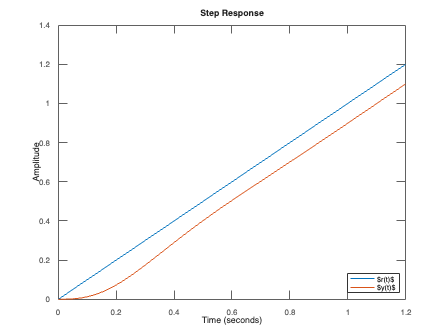


R = 1/s^2;

figure,hold on
step(R*s,1.2)
step(T/s,1.2)

legend('$r(t)$','$y(t)$',Interpreter = 'latex',location='southeast')

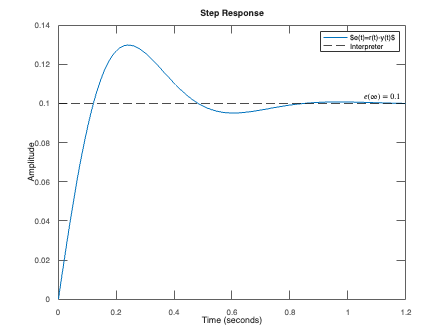


figure,hold on
step(1/(1+L)/s)
yline(1/10,'--k',['$e(\infty)=$',num2str(1/10)],Interpreter='latex')
legend('$e(t)=r(t)-y(t)$',Interpreter = 'latex')

### 10.4.4 Parabolic inputs

Given a unit parabolic input of $R(s)=1/s^3$, the corresponding steady-error is

$e_\infty=\lim_{s\rightarrow 0}\frac{s}{1+L(s)}R(s)=\lim_{s\rightarrow 0}\frac{s}{1+L(s)}\frac{1}{s^3}=\lim_{s\rightarrow 0}\frac{1}{s^2+ s^2L(s)}=\frac{1}{\lim_{s\rightarrow 0}s^2L(s)}$.

Therefore, in order to have zero steady-state error tracking for a parabolic input, we require $\lim_{s\rightarrow 0}s^2L(s)=\infty$. Reflecting on the forward transfer function of


$$\begin{array}{ll}
L(s) &= A_L \frac{ (s-z_1)(s-z_2) \ldots (s-z_m) }{ s^k(s-p_1)(s-p_2) \ldots (s-p_{n-k})}, \\
&= A_L\frac{\prod_{i=1}^m (s-z_i)}{s^k\prod_{i=1}^{n-k} (s-p_i)},
\end{array}$$


we require $k\geq 3$ in order to satisfy $\lim_{s\rightarrow 0}s^2L(s)=\infty$, and by extension, $e(\infty)=0$.

If $k=2$, then 

$\lim_{s\rightarrow 0}s^2L(s)=A_L(-1)^{m+n-2}\frac{z_1z_2...z_m}{p_1p_2...p_{n-2}}$,

and $e(\infty)$ will be finite. This leads to a constant error, which can be thought of as a parabolic response with the same acceleration as the reference, but with a constant offset.

If $k\leq 1$, then 

$\lim_{s\rightarrow 0}s^2L(s)=0$,

and the corresponding $e(\infty)=\infty$. 

## 10.5 Static error constants

We previously defined the steady-state error of a stable closed-loop system to be

$e(\infty)=\lim_{s\rightarrow 0}sE(s)=\lim_{s\rightarrow 0}\frac{s}{1+L(s)}R(s)$.

In the following sections, we will show that by determining the position, velocity, and acceleration error constants, we can thust determine the closed-loop system's ability to track the aforementioned test inputs.

### 10.5.1 Position error constant

Given a unit step input, the steady-state error follows as

$e_p(\infty)=\frac{1}{1+\lim_{s\rightarrow 0} L(s)}=\frac{1}{1+G_{dc}}$.

The **position error constant**, $K_p$, is defined as

$K_p=\lim_{s\rightarrow 0} L(s)$,

which is equivalent to our definition of dc gain, $G_{dc}$. The steady-state position error can then be written in terms of the position constant as

$e_p(\infty)=\frac{1}{1+K_p}$.

If we can determine $K_p$, we can then find the steady-state error directly.

### 10.5.2 Velocity error constant

Given a unit ramp input, the steady-state error follows as

$e_v(\infty)=\frac{1}{\lim_{s\rightarrow 0}sL(s)}$.

The **velocity error constant**, $K_v$, is defined as

$K_v=\lim_{s\rightarrow 0} sL(s)$.

The steady-state velocity error can then be written in terms of the velocity constant as

$e_v(\infty)=\frac{1}{K_v}$.

### 10.5.3 Acceleration error constant

Given a unit parabolic input, the steady-state error follows as

$e_a(\infty)=\frac{1}{\lim_{s\rightarrow 0}s^2L(s)}$.

The **acceleration error constant**, $K_a$, is defined as

$K_a=\lim_{s\rightarrow 0} s^2L(s)$.

The steady-state acceleration error can then be written in terms of the acceleration constant as

$e_a(\infty)=\frac{1}{K_a}$.

## 10.6 System type number

The values of the static error constants (and by extension, the steady-state errors) are dependent on the number of integrators in $L(s)=P(s)G(s)$. Given the description of our forward path below


$$\begin{array}{ll}
L(s) &= A_L \frac{ (s-z_1)(s-z_2) \ldots (s-z_m) }{ s^k(s-p_1)(s-p_2) \ldots (s-p_{n-k})}, \\
&= A_L\frac{\prod_{i=1}^m (s-z_i)}{s^k\prod_{i=1}^{n-k} (s-p_i)},
\end{array}$$


we define the **system type** **number** to be equal to $k$, which corresponds with the number of integrators in $L(s)$. In summary:

- $k=0$ implies that the system is Type-0.

- $k=1$ implies that the system is Type-1.

- $k=2$ implies that the system is Type-2.

In general, loop transfer function $L(s)$ with $k$ integrators is referred to as a Type-$k$ system. Table 10.1 provides a summary of the resulting steady-state errors as a function of the particular test input and system type number.

**Table 10.1**: Summary of steady-state errors, error constants, and associated system types.


$$\left.
\begin{array}{c|ccc}
\\
~ & \text{Type-0} & \text{Type-1} &  \text{Type-2}
\\
\hline
K_p=\lim_{s\rightarrow 0}L(s) \quad& A_L(-1)^{m+n}\frac{z_1z_2...z_m}{p_1p_2...p_n} \quad & \infty & \infty
\\
K_v=\lim_{s\rightarrow 0}sL(s) \quad& 0 \quad & A_L(-1)^{m+n-1}\frac{z_1z_2...z_m}{p_1p_2...p_{n-1}} & \infty
\\
K_a=\lim_{s\rightarrow 0}s^2L(s) \quad& 0 \quad & 0 & A_L(-1)^{m+n-2}\frac{z_1z_2...z_m}{p_1p_2...p_{n-2}}
\\
e(\infty),~r(t)=1 \quad& \frac{1}{1+K_p} \quad & 0 & 0
\\
e(\infty),~r(t)=t \quad& \infty \quad & \frac{1}{K_v} & 0
\\
e(\infty),~r(t)=\frac{t^2}{2} \quad& \infty \quad & \infty & \frac{1}{K_a}
\\
\end{array}
\right.
$$


## 10.7 Steady-state error specifications

### 10.7.1 Feedback control in an error specification

The steady-state error specification can be used to inform how we design a feedback controller at low frequencies. Consider the two equivalent feedback systems shown in Figure 10.8, where

$L(s)=P(s)G(s)$.

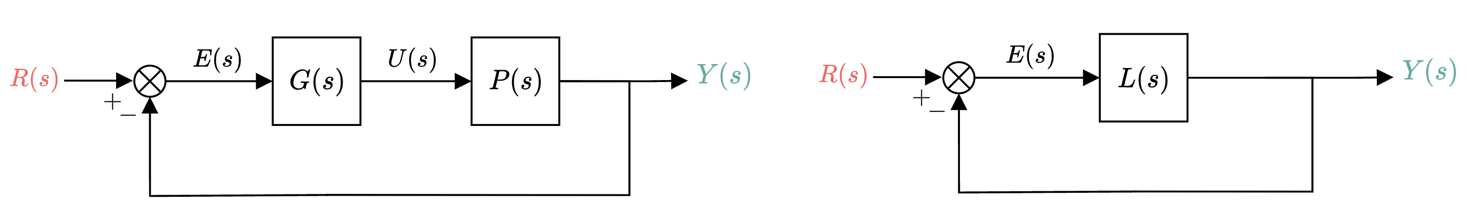

**Figure 10.8 **: Equivalent closed-loop systems.

The feedback controller, $G(s)$, can be an analogue circuit (e.g. an operational amplifier), or a digital device (e.g. a microcontroller), whereas the transfer function $P(s)$ represents the uncontrolled system under consideration. 

As shown before, we can use block diagram reduction or first principles to determine the closed-loop transfer behaviour from $R(s)$ to $E(s)$, namely

$E(s)=\frac{1}{1+L(s)}R(s)=\frac{1}{1+P(s)G(s)}R(s)$.

Applying final value theorem to $E(s)$ results in

$e(\infty)=\lim_{s\rightarrow 0}sE(s)=\lim_{s\rightarrow 0}\frac{s}{1+P(s)G(s)}R(s)$.

The simplest type of feedback controller takes the form of a static gain term, which is expressed as

$G(s)=K$.

This type of controller is known as a proportional controller, as the resulting control action, $U(s)=KE(s)$, is proportional to the tracking error. While we will consider more complicated feedback controllers in this course, it is useful to consider our feedback controller as a simple gain term that is constant across all frequencies. The description of $E(s)$ follows as

$E(s)=\frac{1}{1+KP(s)}R(s)$,

with a corresponding steady-state error of

$e(\infty)=\lim_{s\rightarrow 0}sE(s)=\lim_{s\rightarrow 0}\frac{s}{1+KP(s)}R(s)$.

### 10.7.2 Proportional control design to meet a steady-state error specification

Depending on the system type number and profile of $R(s)$, we can use $K$ to adjust the finite steady-state tracking error as we require.

If $P(s)$ is Type-$k$, then $L(s)=G(s)P(s)=KP(s)$ will be Type-$k$, as $G(s)=K$ does not contribute any integrators. In other words, changing the value of non-zero $K$ will only affect finite steady-state error tracking. This means that if $P(s)$ is Type-$0$, we can use $G(s)=K$ to adjust the finite steady-state error for step references, whereas if $P(s)$ is Type-$1$, we can adjust the finite steady-state error for ramp references. Finally, if $P(s)$ is Type-$2$, we can adjust the finite steady-state error for parabolic references.

For unit *step* references, a finite steady-state error results when $P(s)$ is Type-$0$, which is described by

$e(\infty)=\frac{1}{1+\lim_{s\rightarrow 0}L(s)}=\frac{1}{1+K\lim_{s\rightarrow 0}P(s)}$.

For unit *ramp* references, a finite steady-state error results when $P(s)$ is Type-$1$, which is described by

$e(\infty)=\frac{1}{\lim_{s\rightarrow 0}sL(s)}=\frac{1}{K\lim_{s\rightarrow 0}sP(s)}$.

For unit *parabolic* references, a finite steady-state error results when $P(s)$ is Type-$2$, which is described by

$e(\infty)=\frac{1}{\lim_{s\rightarrow 0}s^2L(s)}=\frac{1}{K\lim_{s\rightarrow 0}s^2P(s)}$.

#### Example

*Determine the value of *$G(s)=K$* that results in a closed-loop steady-state error of *$e(\infty)=0.1$*for the system *$P(s)=\frac{1}{s(s+1)}$*.*

The open-loop system is Type-$1$, so a finite steady-state error results when a ramp reference signal is applied. We set the finite steady-state error for ramp references equal to the desired steady-state value of $e(\infty)=0.1$, namely

$e(\infty)=\frac{1}{K\lim_{s\rightarrow 0}sP(s)}=0.1$.

We can determine that $\lim_{s\rightarrow 0}sP(s)=1$, which implies that $K=10$ is required in order to achieve the desired closed-loop steady-state error.

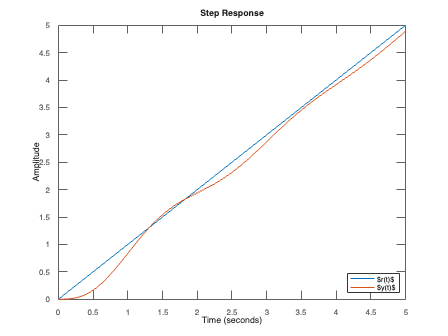

clear
s = tf('s');
P = 1/( s*(s+1) );
G = 10;
L = P*G;

T = feedback(L,1);

figure, hold on
step(1/s,5)
step(T/s,5)
legend('$r(t)$','$y(t)$',Interpreter = 'latex',location='southeast')

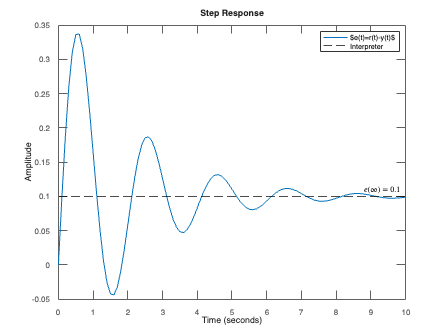


figure,hold on
step(1/(1+L)/s,10)
yline(0.1,'--k',['$e(\infty)=$',num2str(0.1)],Interpreter='latex')
legend('$e(t)=r(t)-y(t)$',Interpreter = 'latex')

Note that although we have achieved the desired steady-state error, our design process has made no consideration for the transient response, which is quite oscillatory. We shall consider the transient behaviour in more detail in the upcoming chapter.

## 10.8 Steady-state error with disturbances 

Feedback control systems are used to compensate for disturbances or unwanted inputs that enter a system. The advantage of using feedback is that regardless of these disturbances, the system can be designed to follow the input with small or zero error at steady-state, as we now demonstrate.

### 10.8.1 Closed-loop error as a function of reference and disturbance

Consider the system in Figure 10.9.

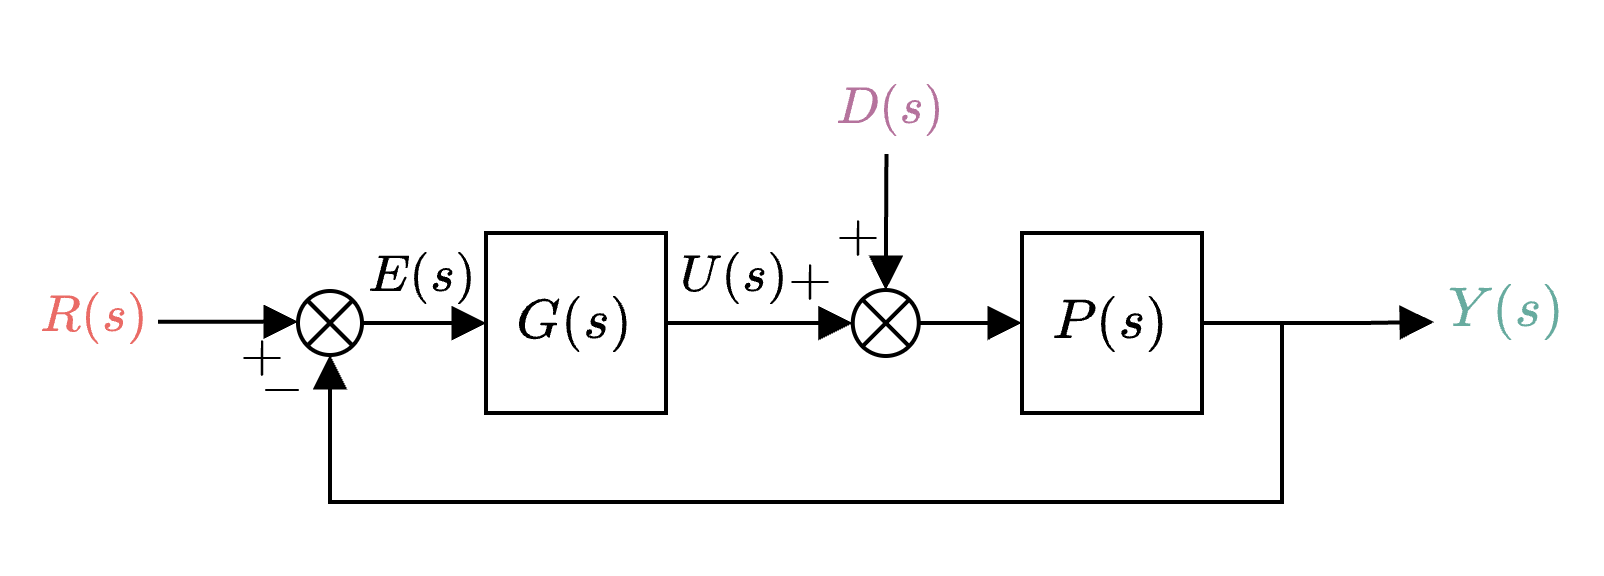

**Figure 10.9 **: Block diagram of closed-loop system with plant input disturbance.

The signal $D(s)$ represents a disturbance that is entering the control system at the plant input. The output signal is derived as

$Y(s)=P(s)G(s)E(s)+P(s)D(s)$.

Additionally, we know that $Y(s)=R(s)-E(s)$. Substituting this into the equation above and rearranging yields

$E(s)=\frac{1}{1+P(s)G(s)}R(s)-\frac{P(s)}{1+P(s)G(s)}D(s)$.

The transfer behaviour, or mapping, from $R(s)$ to $E(s)$ is described by the sensitivity function, $S(s)=\frac{1}{1+P(s)G(s)}$, and the transfer behaviour from $D(s)$ to $E(s)$ is the negative of the load sensitivity function, $-PS(s)=\frac{-P(s)}{1+P(s)G(s)}$.

We determine the steady-state error as before using final value theorem

$e(\infty)=\lim_{s\rightarrow 0}sE(s)=\lim_{s\rightarrow 0}\frac{s}{1+P(s)G(s)}R(s)-\lim_{s\rightarrow 0}\frac{sP(s)}{1+P(s)G(s)}D(s)$,

which can be written compactly as

$e(\infty)=e_R(\infty)+e_D(\infty)$,

where 

- 
$$e_R(\infty)=\lim_{s\rightarrow 0}\frac{s}{1+P(s)G(s)}R(s)$$
  

- 
$$e_D(\infty) = -\lim_{s\rightarrow 0}\frac{sP(s)}{1+P(s)G(s)}D(s)$$


The term $e_R(\infty)$ is the component of the steady-state error as a result of the reference signal, $R(s)$, which we have assessed in the preceding sections of this chapter. The term $e_D(\infty)$ is the component of the steady-state error as a result of the disturbance, $D(s)$, which we will now consider in isolation.

### 10.8.2 Steady-state error for step-like disturbances

Assuming that $D(s)=1/s$, which is most prevalent in real-world systems, the steady-state error as a result of $D(s)$ can be reposed as

$e_D(\infty) = -\lim_{s\rightarrow 0}\frac{P(s)}{1+P(s)G(s)}=-\lim_{s\rightarrow 0}\frac{1}{\frac{1}{P(s)}+G(s)}$.

Assuming $\lim_{s\rightarrow 0}P(s)\neq0$ (the open-loop system does not have a DC gain of zero), we can infer that $e_D(\infty)$ will only tend to zero if the DC gain of $G(s)$ tends to infinity, namely 

$\lim_{s\rightarrow 0}G(s)=\infty$. 

In other words, we require $G(s)$ to be at least Type-$1$ (have at least one integrator), in order to completely reject step-like plant input disturbances at steady-state. We also note in general that increasing the DC gain of $G(s)$ or decreasing the DC gain of $P(s)$ will decrease the steady-error as a result of step-like$D(s)$. Importantly, the Type number of $P(s)$ plays no role in ensuring zero-error steady-state disturbance rejection, which is contrary to when we considered steady-state error for reference signals.

#### Example 1

*Determine the steady-state error, *$e(\infty)$*, when a disturbance of *$D(s)=1/s$* is applied at the plant input of the closed-loop system, where *$P(s)=\frac{1}{s}$* and *$G(s)=K$*. You can assume that *$R(s)=0$*.*

Given that $R(s)=0$, the steady-state error is solely contributed by the disturance, namely

$e(\infty)=e_D(\infty)=-\lim_{s\rightarrow 0}\frac{1}{\frac{1}{P(s)}+G(s)}$.

We can therefore determine the steady-state error as

$e(\infty)=-\lim_{s\rightarrow 0}\frac{1}{\frac{1}{P(s)}+G(s)}=-\frac{1}{0+K}=-\frac{1}{K}$.

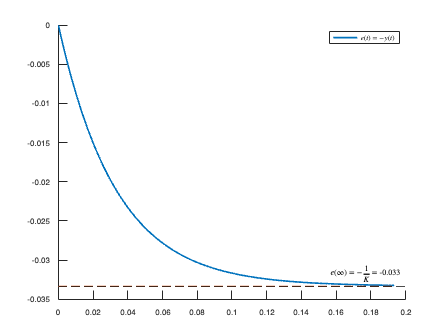

clear
s = tf('s');
P = 1/s;
K = 30;
L = P*K;

[e,t] = step(-P/(1+L));
figure,hold on
plot(t,e,LineWidth=2)
line([t(1) t(end)],[-1/K -1/K],'lineStyle','--')
% text(-0.028,-1/K,'$e(\infty)=-\frac{1}{K}$','Color','red','Interpreter','latex')
yline(-1/K,'--k',['$e(\infty)=-\frac{1}{K}=$',num2str(-1/K,2)],Interpreter='latex')
legend('$e(t)=-y(t)$',Interpreter = 'latex')

Note that regardless of $P(s)$ possessing an integrator, finite $K$ never be large enough to fully reject the disturbance based on the equation above.

#### Example 2

*Determine the steady-state error, *$e(\infty)$*, when a disturbance of *$D(s)=1/s$* is applied at the plant input of the closed-loop system, where *$P(s)=\frac{1}{s}$* and *$G(s)=K\frac{1+s}{s}$*. You can assume that *$R(s)=0$*.*

Given that $R(s)=0$, the steady-state error is solely contributed by the disturbance, namely

$e(\infty)=e_D(\infty)=-\lim_{s\rightarrow 0}\frac{1}{\frac{1}{P(s)}+G(s)}$.

We can therefore determine the steady-state error as

$e(\infty)=-\lim_{s\rightarrow 0}\frac{1}{\frac{1}{P(s)}+G(s)}=-\frac{1}{0+\infty}=0$.

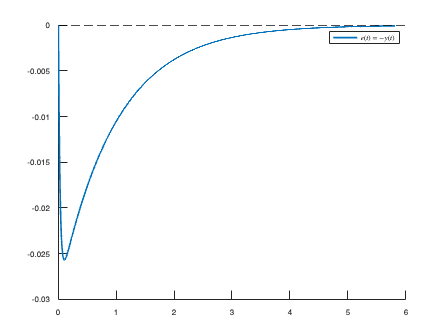

clear
s = tf('s');
P = 1/s;
K = 36;
G = K*(1+s)/s;
L = P*G;

[e,t] = step(-P/(1+L));
figure,hold on
plot(t,e,LineWidth=2)
yline(0,'--k',['$e(\infty)=0$'],Interpreter='latex')

legend('$e(t)=-y(t)$',Interpreter = 'latex')

The inclusion of an integrator in $G(s)$ results in $G(s)$ having an infinitly large DC gain, which results in $e(\infty)\rightarrow 0$. This highlights the importance of the Type number of the feedback controller when dealing with disturbance signals.

## 10.9 Steady-state error characteristics from frequency response

With reference to Figure 10.10, our complementary sensitivity function is given by $T(s)=\frac{L(s)}{1+L(s)}$, where 

$\begin{array}{ll}
L(s)
&= A_L\frac{\prod_{i=1}^m (s-z_i)}{s^k\prod_{i=1}^{n-k} (s-p_i)}
\end{array}$.

**Figure 10.10 **: Block diagram of closed-loop system.

We can use the frequency response of $L(s)$ to determine the static error constants, and by extension, the expected steady-state error behaviour for a given reference signal. This is important when assessing steady-state error requirements during the design stage.

Recall that:

- $K_p=\lim_{s\rightarrow 0} L(s)$ is the position error constant.

- $K_v=\lim_{s\rightarrow 0} sL(s)$ is the velocity error constant.

- $K_a=\lim_{s\rightarrow 0} s^2L(s)$ is the acceleration error constant.

### 10.9.1 Position error constant

Consider a Type-0 open-loop system ($k=0$) of the form


$$\begin{array}{ll}
L(s)
&= A_L\frac{\prod_{i=1}^m (s-z_i)}{s^k\prod_{i=1}^{n-k} (s-p_i)}
= A_L\frac{\prod_{i=1}^m (s-z_i)}{\prod_{i=1}^{n} (s-p_i)}.
\end{array}$$


The low-frequency gain of $L(s)$ for $k=0$ is determined as

$G_{dc}=\lim_{s\rightarrow 0}A_L\frac{\prod_{i=1}^m(s-z_i)}{\prod_{i=1}^n(s-p_i)}=A_L(-1)^{m+n}\frac{\prod_{i=1}^{m} z_i}{\prod_{i=1}^{n-k} p_i}$.

On a Bode magnitude response, this is represented as $20\log_{10}|G_{dc}|$, which occurs when $\omega=0$ rad/s. We also know that $K_p=G_{dc}$. Therefore we can determine 

$K_p=G_{dc}=A_L(-1)^{m+n}\frac{\prod_{i=1}^{m} z_i}{\prod_{i=1}^{n-k} p_i}$,

where the low-frequency axis value is $20\log_{10}|K_p|$ as shown in Figure 10.11.

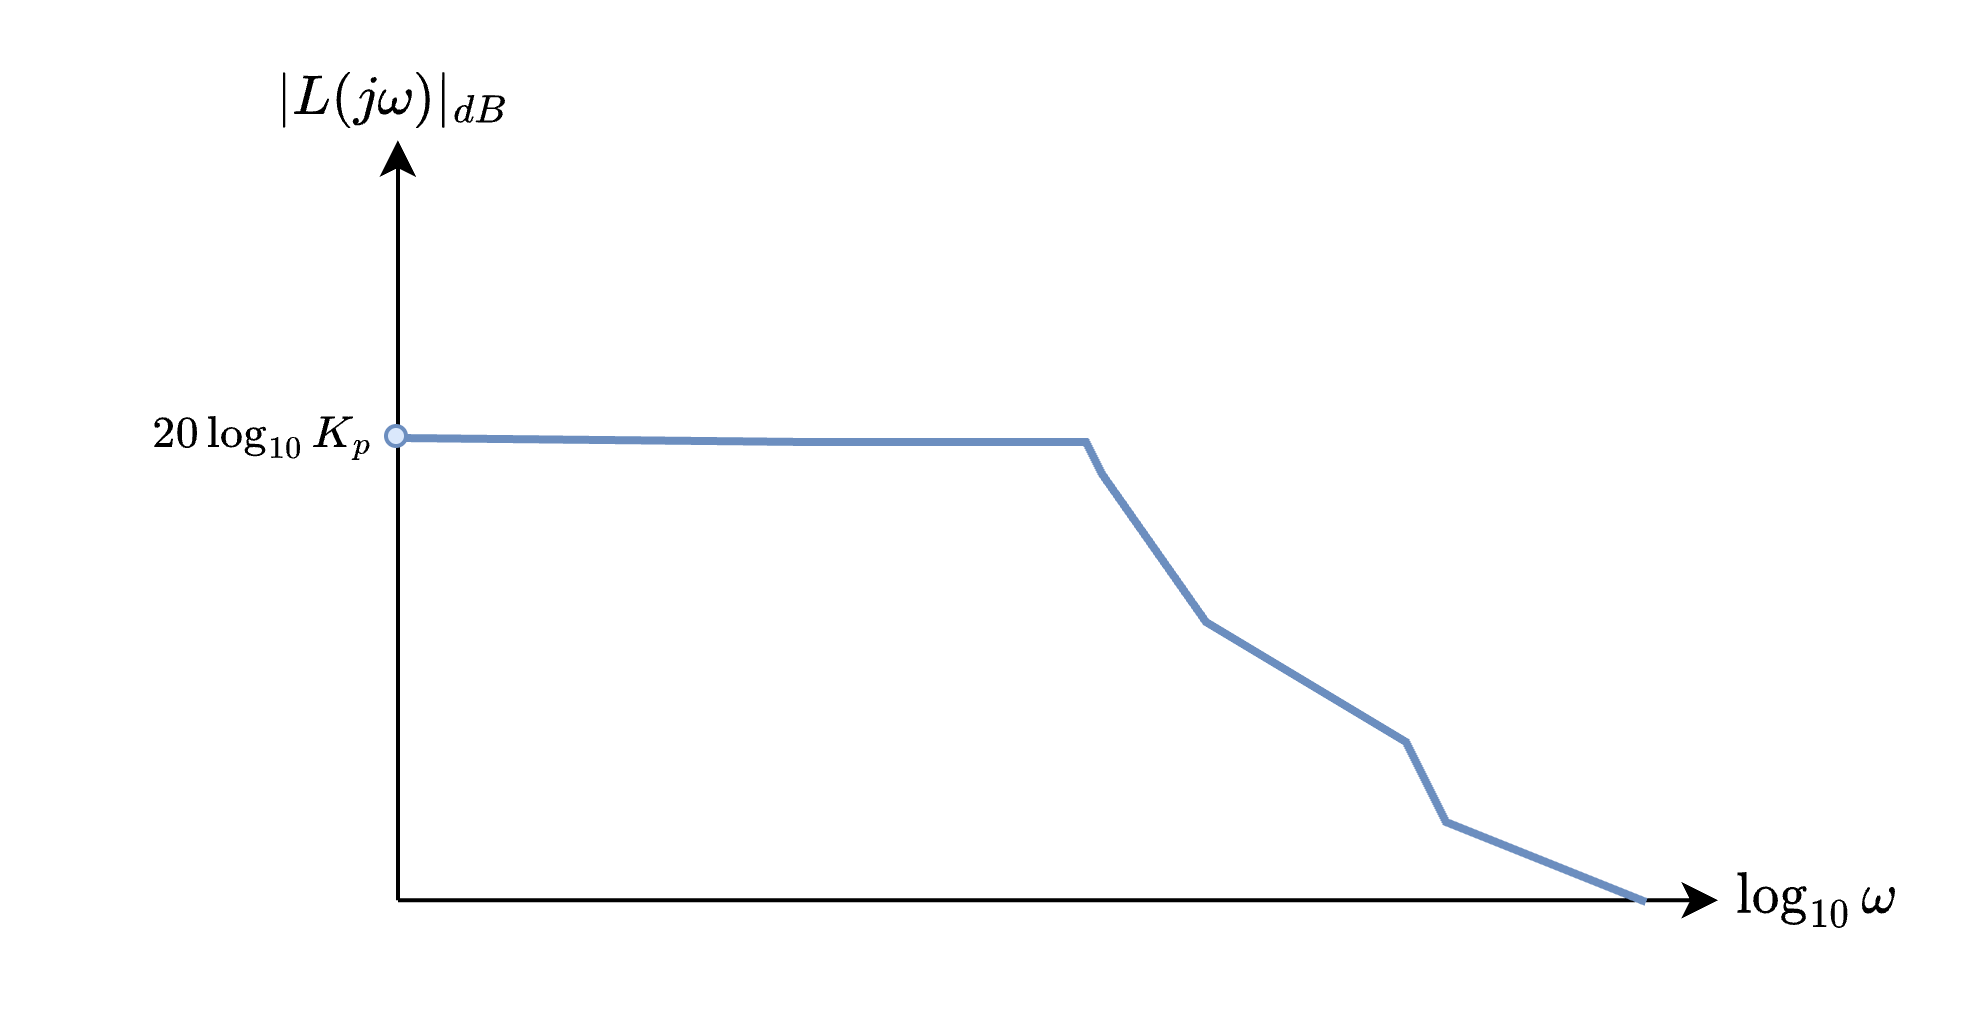

**Figure 10.11 **: Frequency response magnitude of loop transfer function, showing determination of position error constant, $K_p$.

If $|L(j\omega)|$ has a flat passband (as shown above), then $K_p$ is finite, and we can expect 

- finite, non-zero position error tracking at steady-state, 

- and infinitely large steady-state error tracking for velocity and acceleration references.

#### Example 

*Using the Bode magnitude response, determine the steady-state error of *$L(s)=\frac{10}{1+s/10}$* when placed in unity-feedback and perturbed by a unit step reference signal.*

The code below generates the Bode magnitude response. From this we can determine the logarithmic position error constant based on the y-intercept, which yields $20\log_{10}K_p=20$. It follows that $K_p=10$, and $e(\infty)=\frac{1}{1+K_p}=\frac{1}{1+10}=0.091$.

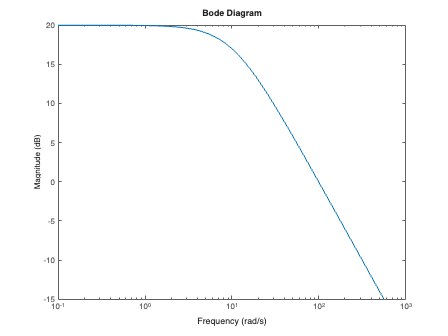

%Example
clear
s = tf('s');
L = 10/(1+s/10);
T = feedback(L,1);

Kp = 10;

figure, hold on
bodemag(L)
yline(20*log10(Kp),'--k',['$20\log K_p=$',num2str(20*log10(Kp)), ' dB'],Interpreter='latex')

ylim([-20 25])

The tracking error vs time is shown using the code below, which matches our interpretation from the Bode diagram.

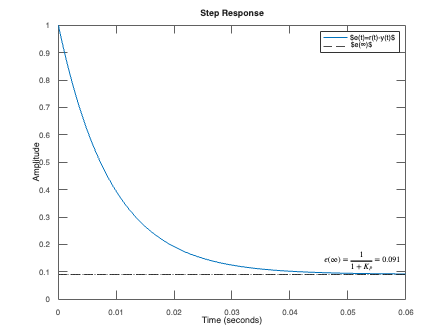

figure,hold on
step(1/(1+L))
yline(1/(1+Kp),'--k',['$e(\infty)=\frac{1}{1+K_p}=$',num2str(1/(1+Kp),2)],Interpreter='latex')
legend('$e(t)=r(t)-y(t)$','$e(\infty)$','Interpreter','latex')

### 10.9.2 Velocity error constant

Consider a Type-1 open-loop system ($k=1$) of the form:


$$\begin{array}{ll}
L(s)
&= A_L\frac{\prod_{i=1}^m (s-z_i)}{s^k\prod_{i=1}^{n-k} (s-p_i)}
= A_L\frac{\prod_{i=1}^m (s-z_i)}{s\prod_{i=1}^{n-1} (s-p_i)}.
\end{array}$$


For $\omega\ll\{z_i,p_k\} ,~\forall i,k$, the low-frequency straight line approximate gain of $|L(j\omega)|$ is  

$|L'(j\omega)|=\frac{A_L}{\omega}\frac{\prod_{i=1}^m|z_i|}{\prod_{i=1}^{n-1}|p_i|}$,

which contributes $-20$ dB/decade roll-off. If $\omega_0$ represents the lowest frequency point used in the Bode magnitude response, then the corresponding magnitude response in dB will be 

$20\log_{10}|L'(j\omega_0)|=20\log_{10}\left( \frac{A_L}{\omega_0}\frac{\prod_{i=1}^m|z_i|}{\prod_{i=1}^{n-1}|p_i|} \right)$.

The magnitude response of $|L'(j\omega)|$ will then intercept the frequency axis (have a logarithmic gain of $0$ dB) when $|L'(j\omega)|=1$, which is at

$\omega=A_L\frac{\prod_{i=1}^m|z_i|}{\prod_{i=1}^{n-1}|p_i|}$.

Given that the velocity error constant is defined as $K_v=\lim_{s\rightarrow 0} sL(s)=A_L\frac{\prod_{i=1}^m|z_i|}{\prod_{i=1}^{n-1}|p_i|}$, we can determine $K_v$ directly, by extending the low-frequency assymptote to the frequency axis, as shown in Figure 10.12. The intersection with the frequency axis is then $K_v$.

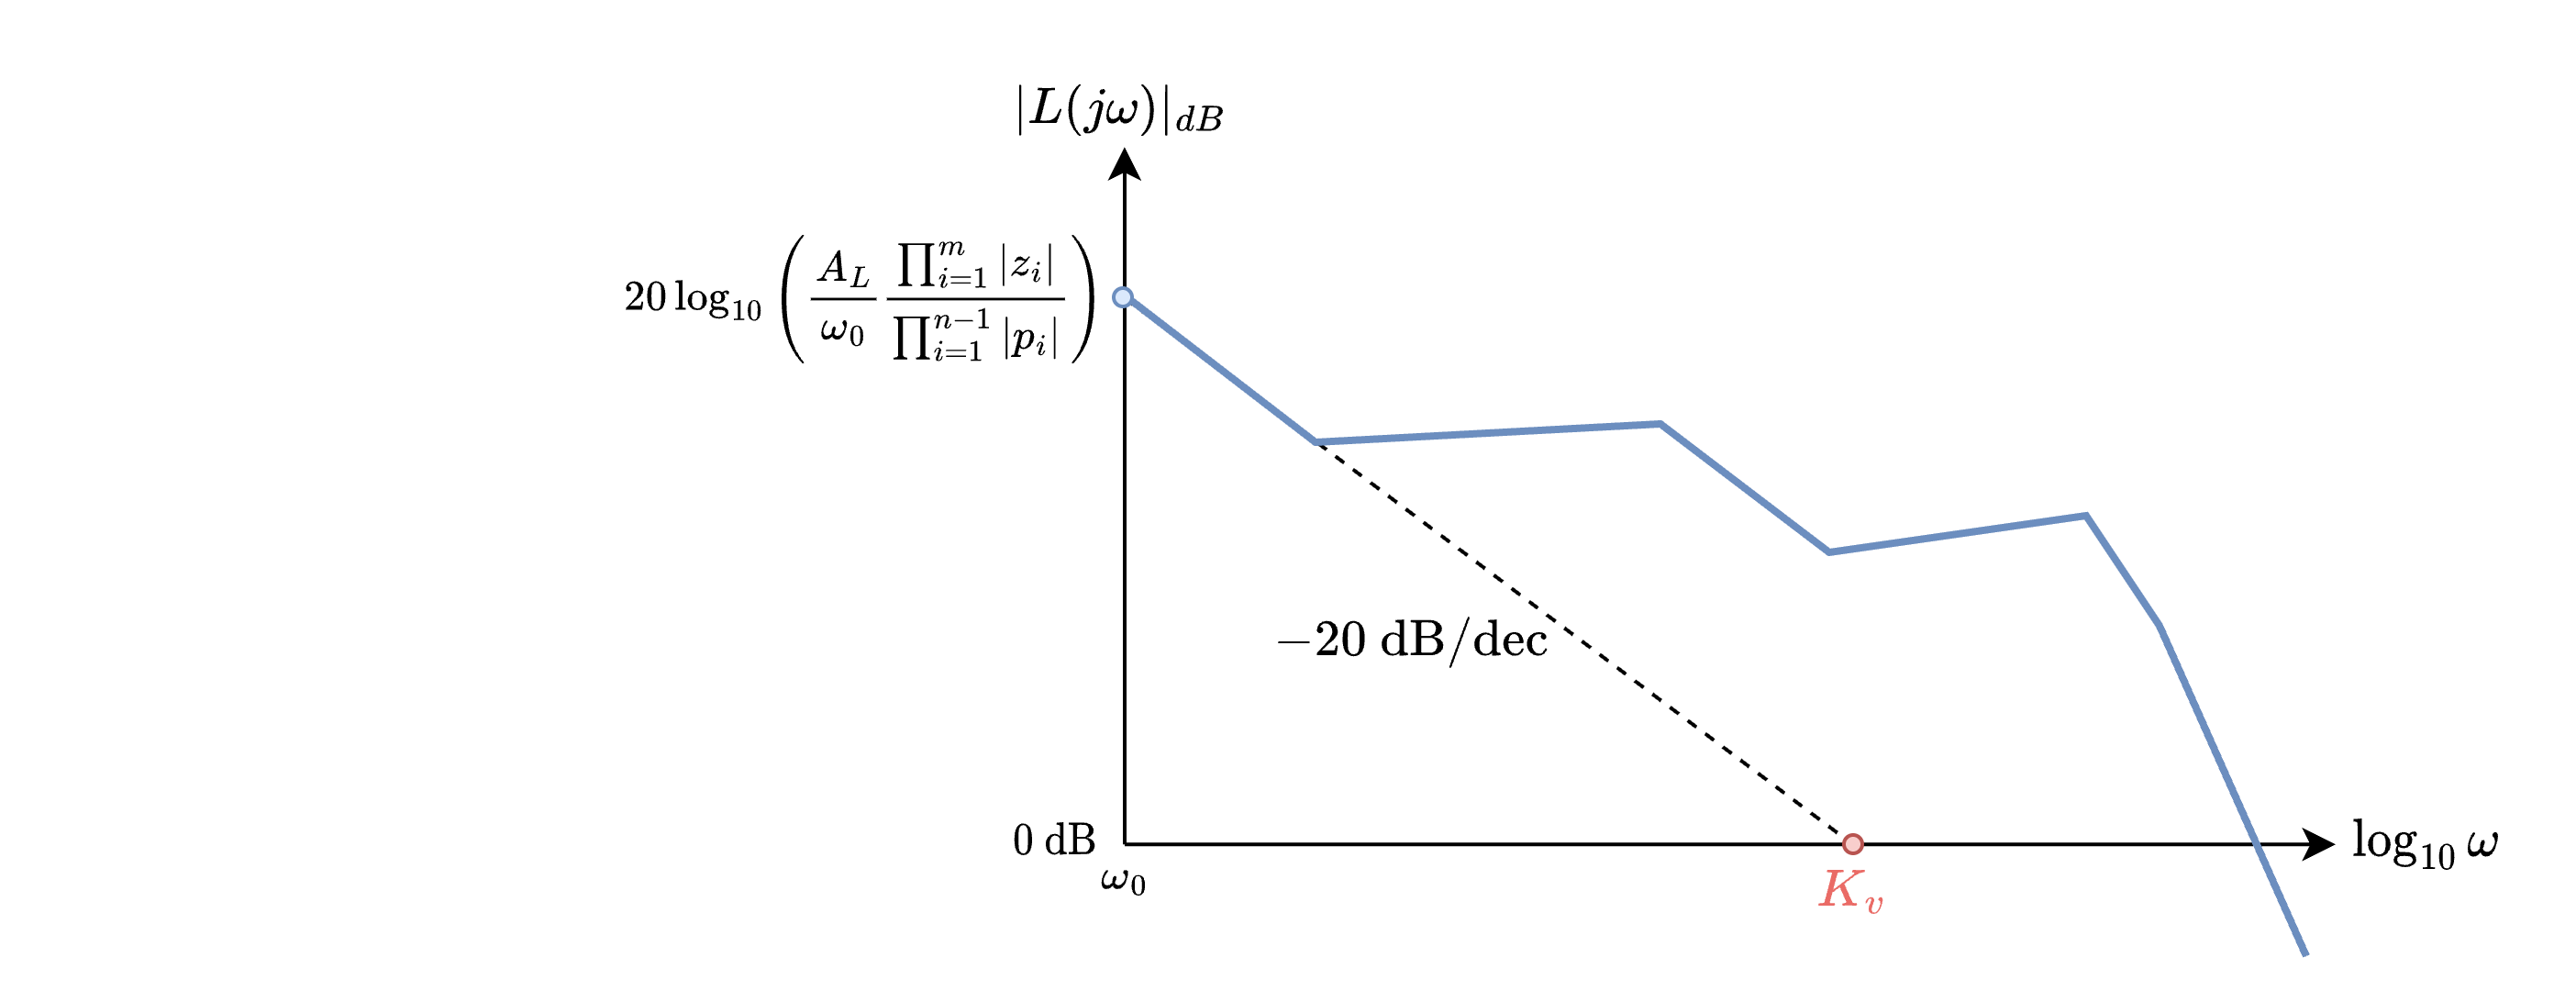

**Figure 10.12 **: Frequency response magnitude of loop transfer function, showing determination of velocity error constant, $K_v$.

We can therefore infer that a a magnitude response that rolls off at $-20$dB/decade at low frequencies will result in 

- zero-error position tracking at steady-state, 

- finite, non-zero velocity error tracking at steady-state, and 

- infinitely large steady-state error tracking for acceleration references.

#### Example

*Using a Bode diagram, determine the steady-state error of *$L(s)=\frac{10}{s(1+s/10)}$* when placed in unity-feedback and perturbed by a unit ramp reference signal.*

The code below generates the Bode magnitude response. From this we can determine the velocity error constant based on the finding the x-intercept of the low-frequency assymptote, which yields $K_v=10$. It follows that $K_p=10$, and $e(\infty)=\frac{1}{K_v}=\frac{1}{10}=0.1$.

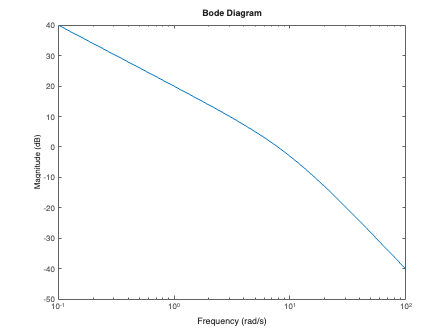

%Example
clear
s = tf('s');
L = 10/s/(1+s/10);
T = feedback(L,1);

Kv = 10;

figure, hold on
bodemag(L,{.1 1e2})
line([0.1 10],[40 0],'lineStyle','--')

ylim([0 50])

The tracking error vs time is shown using the code below, which matches our interpretation from the Bode diagram.

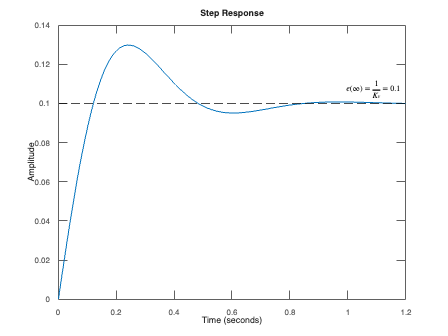

figure,hold on
step(1/(1+L)/s)
yline(1/Kv,'--k',['$e(\infty)=\frac{1}{K_v}=$',num2str(1/Kv)],Interpreter='latex')

### 10.9.3 Acceleration error constant

Consider a Type-2 system ($k=2$) of the form:


$$\begin{array}{ll}
L(s)
&= A_L\frac{\prod_{i=1}^m (s-z_i)}{s^k\prod_{i=1}^{n-k} (s-p_i)}
= A_L\frac{\prod_{i=1}^m (s-z_i)}{s^2\prod_{i=1}^{n-2} (s-p_i)}.
\end{array}$$


For $\omega\ll\{z_i,p_k\} ,~\forall i,k$, the straight line approximate gain of $|L(j\omega)|$ is  

$|L'(j\omega)|=\frac{A_L}{\omega^2}\frac{\prod_{i=1}^m|z_i|}{\prod_{i=1}^{n-2}|p_i|}$,

which contributes $-40$dB/decade roll-off. If $\omega_0$ represents the lowest frequency point used when visualising the Bode magnitude response, then the corresponding magnitude response in dB will be 

$20\log_{10}|L'(j\omega_0)|=20\log_{10}\left( \frac{A_L}{\omega_0^2}\frac{\prod_{i=1}^m|z_i|}{\prod_{i=1}^{n-2}|p_i|} \right)$.

The magnitude response of $|L'(j\omega)|$ will then intercept the frequency axis when $|L'(j\omega)|=1$ (or $0$ in logarithmic units), which is at

$\omega=\sqrt{A_L\frac{\prod_{i=1}^m|z_i|}{\prod_{i=1}^{n-2}|p_i|}}$.

Given that the acceleration error constant is defined as 

$K_a=\lim_{s\rightarrow 0} s^2L(s)=A_L\frac{\prod_{i=1}^m|z_i|}{\prod_{i=1}^{n-2}|p_i|}$, 

we can determine $K_a$ directly by extending the low-frequency assymptote to the frequency axis, as shown in Figure 10.13. The intersection with the frequency axis is then $\sqrt{K_a}$.

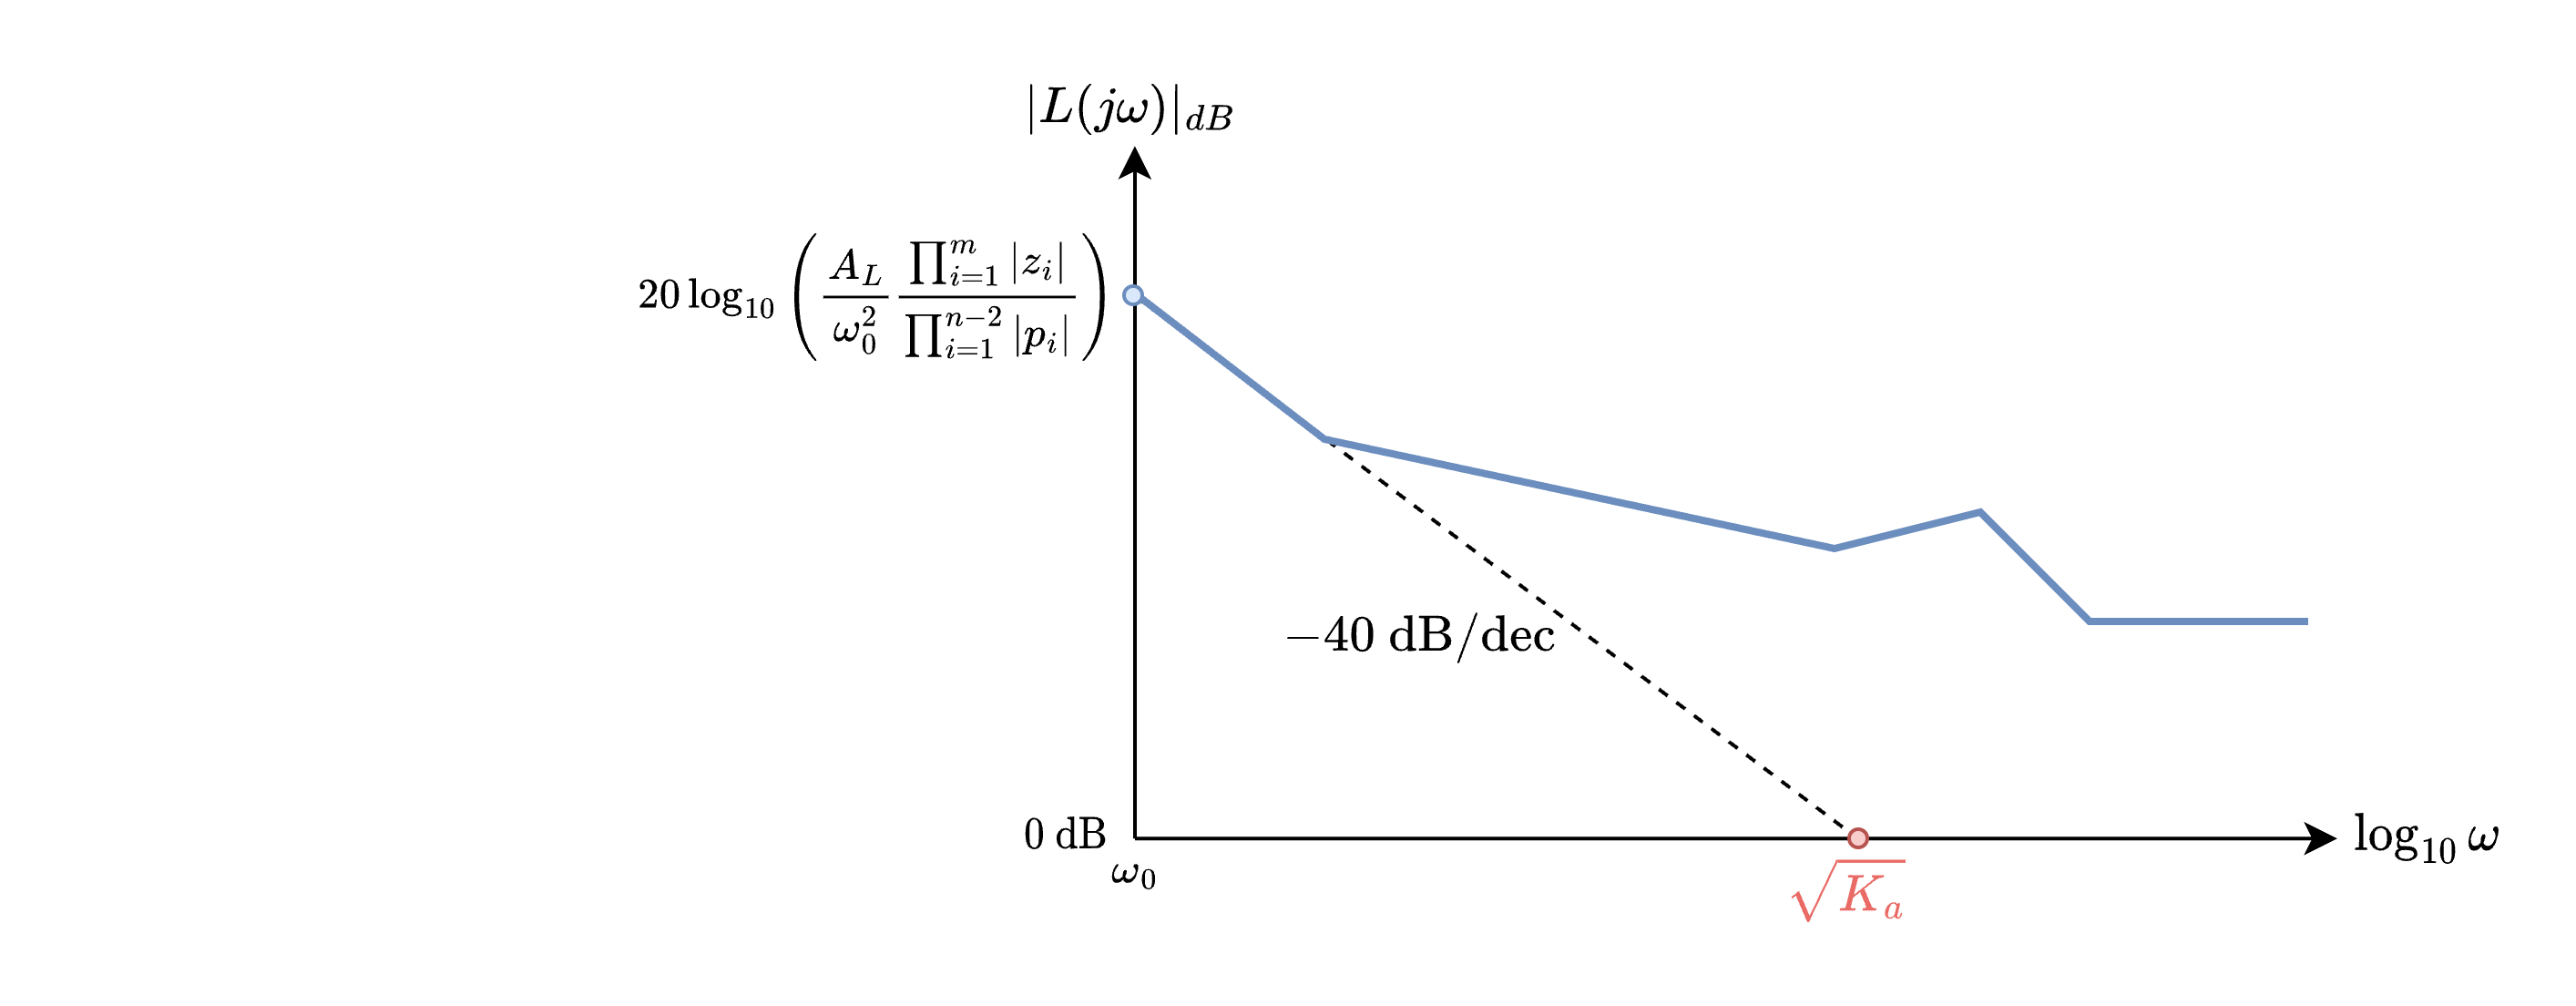

**Figure 10.13 **: Frequency response magnitude of loop transfer function, showing determination of acceleration error constant, $K_a$.

We can therefore infer that if $L(j\omega)$ has a magnitude response that rolls off at $-40$dB/decade at low frequencies, this will result in 

- zero-error position and velocity tracking at steady-state, and 

- finite, non-zero acceleration error tracking at steady-state.